# Secure Quantum Data Communication Simulation    

    This script demonstrates how the encryption scheme is used for sending data from one party "Alice" to another party "Bob". in this simulation Alice is sending the message "hello" to Bob, we can see the original binary representation of this message which will then get fed into our quantum circuit. In the quantum circuit the encryption results in blocks where the quantum state is unrecognizable from the original data. Then Bob takes in this data and decrypts it to get the original binary data then converts it back into plain text to display the original message. 

%File for demo
%Initialization
Alice = sender();
Bob = receiver();

Alice.makeCliffordGates();
Bob.makeCliffordGates();
Alice.setPermSet();
Bob.setPermSet();

codeword = Alice.messageToBinary("hello")

codeword = 14×1 string array
    "011"
    "010"
    "000"
    "110"
    "010"
    "101"
    "101"
    "100"
    "011"
    "011"
    "000"
    "110"
    "111"
    "100"


encrypted_states = Alice.encrypt(codeword);
%Show the first 3 blocks of encrypted data
for i=1:3
    X = ['Block number ',num2str(i),':'];
    disp(X)
    disp(formula(encrypted_states{i}));
end

Block number 1:


(-0.17678+0.17678i) * |00000> +
(-0.17678-0.17678i) * |00010> +
(-0.17678-0.17678i) * |00100> +
(-0.17678+0.17678i) * |00110> +
(0.17678+0.17678i)  * |01000> +
(-0.17678+0.17678i) * |01010> +
(-0.17678+0.17678i) * |01100> +
(0.17678+0.17678i)  * |01110> +
(0.17678+0.17678i)  * |10001> +
(0.17678-0.17678i)  * |10011> +
(0.17678-0.17678i)  * |10101> +
(0.17678+0.17678i)  * |10111> +
(0.17678-0.17678i)  * |11001> +
(-0.17678-0.17678i) * |11011> +
(-0.17678-0.17678i) * |11101> +
(0.17678-0.17678i)  * |11111>


Block number 2:


(-5.5792e-18+0.25i) * |00000> +
(5.5792e-18+0.25i)  * |00001> +
(-5.5792e-18-0.25i) * |00010> +
(-5.5792e-18+0.25i) * |00011> +
(5.5792e-18+0.25i)  * |00100> +
(-5.5792e-18+0.25i) * |00101> +
(5.5792e-18-0.25i)  * |00110> +
(5.5792e-18+0.25i)  * |00111> +
(-0.25-5.5792e-18i) * |10000> +
(-0.25+5.5792e-18i) * |10001> +
(0.25-5.5792e-18i)  * |10010> +
(-0.25-5.5792e-18i) * |10011> +
(0.25-5.5792e-18i)  * |10100> +
(0.25+5.5792e-18i)  * |10101> +
(-0.25-5.5792e-18i) * |10110> +
(0.25-5.5792e-18i)  * |10111>


Block number 3:


(-0.25+2.634e-18i)  * |00000> +
(-1.101e-17+0.25i)  * |00011> +
(-2.634e-18+0.25i)  * |00100> +
(-0.25+2.634e-18i)  * |00111> +
(-5.742e-18+0.25i)  * |01001> +
(0.25+2.634e-18i)   * |01010> +
(0.25+2.634e-18i)   * |01101> +
(2.634e-18+0.25i)   * |01110> +
(-7.5405e-18+0.25i) * |10000> +
(0.25-2.634e-18i)   * |10011> +
(-0.25-5.742e-18i)  * |10100> +
(2.634e-18-0.25i)   * |10111> +
(-0.25-2.634e-18i)  * |11001> +
(-2.2725e-18+0.25i) * |11010> +
(-2.634e-18-0.25i)  * |11101> +
(0.25+1.101e-17i)   * |11110>


decoded = Bob.decode(encrypted_states);
%Show first 3 blocks
for i=1:3
    X = ['Block number ',num2str(i),':'];
    disp(X)
    disp(decoded{i});
end

Block number 1:


011


Block number 2:


010


Block number 3:


000


received_message = Bob.binaryToMessage(decoded);
disp(received_message);

hello


Below here we can see an example of the quantum circuit of Clifford gates generated by Alice and Bob. We can see that they are both correctly generating the same quantum circuit as a result of their random number generators being seeded the same.

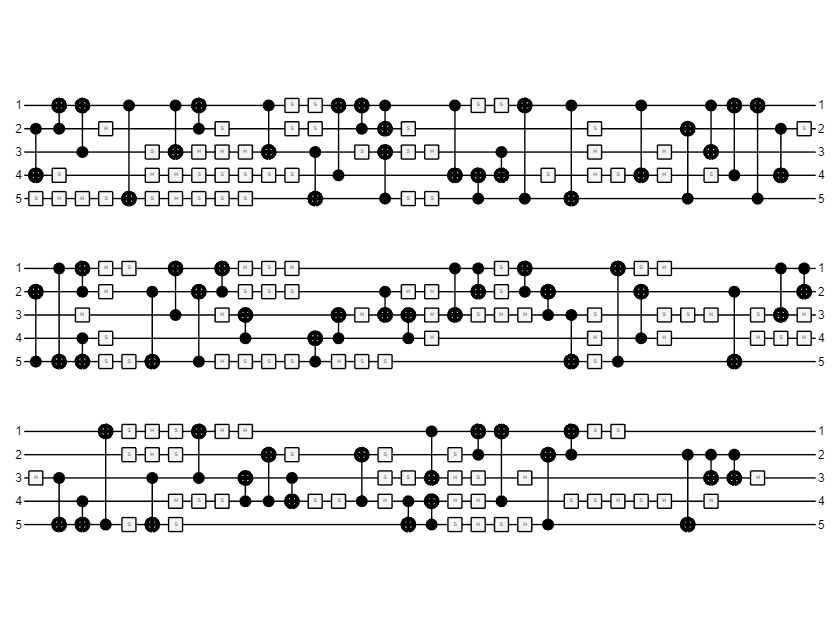

gates = [ Alice.clifford_gates{1}];
C = quantumCircuit(gates);
plot(C);

gates = [ Bob.clifford_gates{1}];
C = quantumCircuit(gates);
plot(C);